# Machine Learning for Regression: Part 2

*An application in electricity load forecasting*

**Suggested Pre-work**

- [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted) – a free two-hour introductory tutorial to learn the essentials of MATLAB.

- [Machine Learning for Regression: Part 1](matlab:open('MachineLearningIntro.mlx'))

## **1. Can you predict future electricity demand?**

The amount of electricity required by an electrical grid is called its **load**, which can vary significantly throughout the day. Forecasting this load helps utility companies plan electricity generation and allows energy traders to anticipate market conditions.

This script uses historical data to predict future electricity demand in New York City. The figures below show an example load profile (left) and the forecast produced by the model (right).

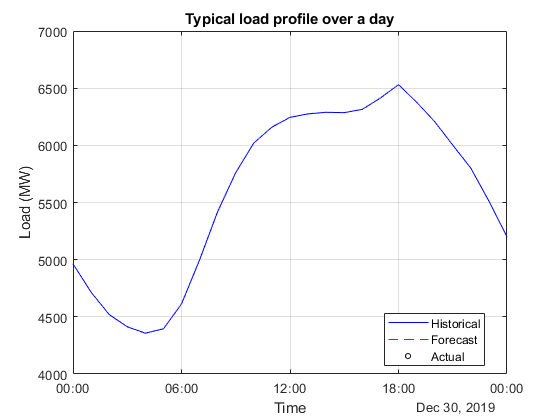   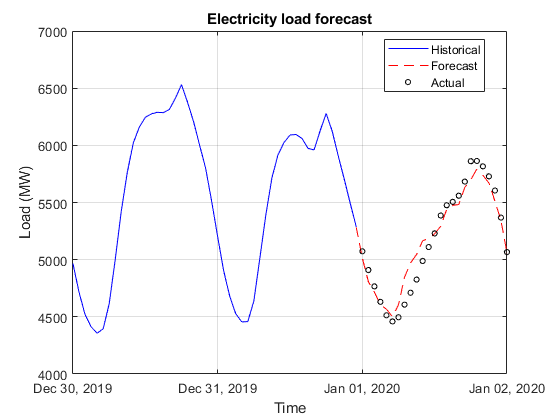

In this script, you will follow the steps of this workflow in MATLAB. The final step for integrating the model in a production environment or a system is optional and not within the scope of this module.

 **For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one.**

Use this script in a controls-only mode (default) by using the **Hide code **  button, or view the code by using the **Output inline**   button on the **View** tab of the MATLAB toolstrip.

### 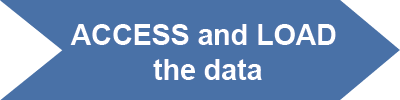

## 2. Access and Load the data

### 2.1. Download the NYISO electricity load data

**NOTE: **This section requires you to download external data from [New York ISO](http://mis.nyiso.com/public/) and take approximately 1-5 minutes (depending on your internet connection). The script `ElectricityLoadDataML.mlx` included with this module downloads, formats, and saves the data.

***Task:**** Click the ****Open script to load data**** button to open ElectricityLoadData*`ML.mlx`*. If viewing code in Output inline mode, you can alternatively use* *the ****Run Section**** button in the MATLAB toolstrip, or click the vertical blue-striped bar on the left to run a section. *

*Set the parameters in this script to download electricity data for the start and end dates given below.*

**          Start date: **`2017-Jan-01`       **         End date:** `2025-Dec-01`

edit ElectricityLoadDataML.mlx
 

View the contents of `nyiso_cleaned.mat` file. It should contain a `timetable` variable named `nyiso`.

whos('-file','nyiso_cleaned.mat')
 

### 2.2. Bring the data into the MATLAB workspace

The very first step is to access the data and get familiar with it. To do this, load the data from `nyiso_cleaned.mat` and inspect the first few rows.

***Task:**** In the edit field below, use the *[`head`](https://www.mathworks.com/help/matlab/ref/table.head.html)* or *[`display`](https://www.mathworks.com/help/matlab/ref/display.html)* function to preview the contents of the variable *`nyiso`*.*

load nyiso_cleaned.mat nyiso;
 
 

### 2.3. Visualize the data

Another way to get familiar with the data is to plot and visualize it.

***Task: ****Select a region (zone) from the* *drop-down list below.*

allregions = string(nyiso.Properties.VariableNames);
region = allregions(9);

% Plot the load profile for the selected region.
figure
plot(nyiso.Date,nyiso{:,region},SeriesIndex = 1)
xlabel("Date")
ylabel("Load (MW)")
title("Raw Data for " + region + " region","Interpreter","none")

### 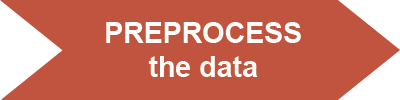

## 2. Preprocess the data

### 2.1. Extract and retime the load data for NYC region

The data in `ElectricityLoadDataML.mlx` has already been prepared by combining monthly CSV files, removing spikes and missing values, and converting the data into suitable MATLAB formats.

Initial analysis shows that electricity usage patterns and average load levels vary by region. Therefore, you will build a separate model for each zone.

***Task: ***Start by extracting the data for New York City zone. After modeling for New York City's electrical load by the end of this script, you can return to this section to repeat the same process for another zone.

% Extract the data for New York City.
allregions = string(nyiso.Properties.VariableNames);
NYCData = nyiso(:,allregions(9));

% Change the table column name to be more general.
NYCData.Properties.VariableNames = "Load"

***Task: ***Your goal in this module is to make hourly forecasts. Use the function [`retime`](https://www.mathworks.com/help/matlab/ref/timetable.retime.html) to resample the `timetable` variable `NYCData` from 5-minute time steps to 1-hour time steps.

NYCHourly = retime(NYCData,'hourly');
NYCHourly = timetable2table(NYCHourly);
NYCHourly(end,:) = []

### 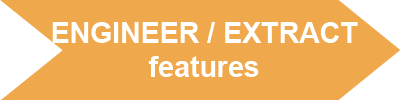

## 3. Engineer/Extract features

### 3.1. Extract **features to apply regression models for load forecasting**

**3.1. Extract Features for Load Forecasting**

Supervised machine learning learns the relationship between input features and an output. Here, the output is the electricity load at a given hour. Because time-series data mainly contain timestamps and measured values, useful features must be created from the historical load data.

One approach is to use **lag features**, which are load values from earlier times. For example, the load from the previous hour can be added as an input column for predicting the current load. Other lags can capture repeating daily, weekly, or yearly patterns. The most useful lags depend on the problem.

For electricity load forecasting, suitable features include the load from the previous hour and from the same hour on previous days or weeks, reflecting the strong hourly, daily, and weekly patterns in electricity demand.

***Task: ****The function *[`lagmatrix`](https://www.mathworks.com/help/releases/R2021a/econ/lagmatrix.html)* is used to extract lag features. Calculate the lags (in number of hours) for the previous hour, the previous day, and the previous week. Enter appropriate lags in the edit fields provided below.*

PreviousHour = NaN;
PreviousDay = NaN;
PreviousWeek = NaN;
 

PreviousLoads = lagmatrix(NYCHourly.Load,[PreviousHour PreviousDay PreviousWeek]);
NYCHourly.PreviousLoad = PreviousLoads(:,1);
NYCHourly.PreviousDayLoad = PreviousLoads(:,2);
NYCHourly.PreviousWeekLoad = PreviousLoads(:,3)

### 3.2. Extract** more temporal features**

Electricity demand varies with the time of day, day of the week, season, and year. For example, demand is typically lower at night, differs between weekdays and weekends, and changes with seasonal heating and cooling needs. Therefore, the hour, day of the week, month, and year can be used as model features.

% Extract the vector containing the dates from the table.
dates = NYCHourly.Date

*The MATLAB functions *[`weekday`](https://www.mathworks.com/help/matlab/ref/weekday.html)*, *[`hour`](https://www.mathworks.com/help/matlab/ref/datetime.hour.html)*, *[`month`](https://www.mathworks.com/help/matlab/ref/datetime.month.html)*, and *[`year`](https://www.mathworks.com/help/matlab/ref/datetime.year.html)* respectively extract the day of week, hour number, month number, and year number from a *[`datetime`](https://www.mathworks.com/help/matlab/ref/datetime.html)* variable. *

*For convenience, the *`datetime`* vector *`dates`* contains the extracted *`Date`* variable from the NYCHourly table. *

NYCHourly.DayOfWeek = ans;
NYCHourly.Hour = ans;

***Task:**** Similarly, replace the code in the edit fields to extract the month and the year from the date. Click ****Extract date time features**** to run the section.*

NYCHourly.Month = ans;
NYCHourly.Year = ans;
 

However, the hour, weekday, and month are cyclical rather than linear. For example, 11 p.m. is closer to 1 a.m. than to 8 p.m. Representing these values as ordinary numbers does not capture this relationship. Instead, each cyclical variable is converted into sine and cosine features.

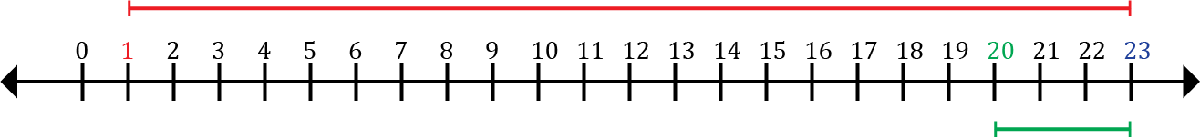                    

               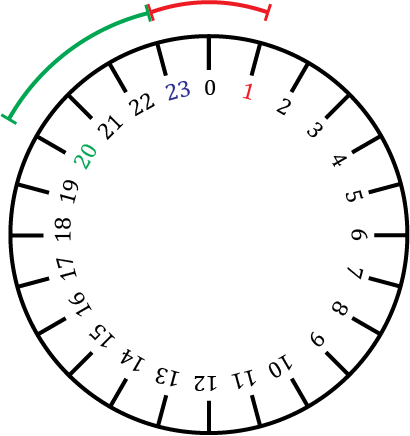

***Task: ****The code for transforming the hour number has been provided below. Perform a similar conversion for month number and day of week variables. Remember that there are 7 days in a week and 12 months in a year. Apply the appropriate scaling in each case.*

% Convert the hours to sin and cos features
NYCHourly.HourX = ans;
NYCHourly.HourY = ans;

% Convert the months to sin and cos features
NYCHourly.MonthX = ans;
NYCHourly.MonthY = ans;

% Convert the days of week to sin and cos features
NYCHourly.DayOfWeekX =ans;
NYCHourly.DayOfWeekY = ans;

 
 NYCHourly

 % Delete the old features
NYCHourly.Hour = [];
NYCHourly.Month = [];
NYCHourly.DayOfWeek = [];

After removing the original hour, weekday, and month variables, the dataset contains ten features that can be used to predict the next hour’s electricity load.

NYCHourly

### 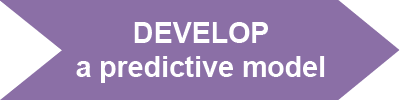

## 4. Develop a predictive model

### 4.1. **Split into training and testing data**

Before training our machine learning models, split the available data into training and test subsets. Use the majority of the available data (Feb 1st, 2017 to Dec 1st, 2022) to train the predictive model and test it on a smaller set (Jan 1st. 2023 to Dec 1st, 2025).

***Task:**** Enter the correct years for the start and end dates of the ****training**** set.*

% Get the indices (row numbers) for training and test based on the range of the Date variable. 
% ***MAKE SURE TO SELECT THE DATES BELOW TO BE WITHIN THE RANGE OF DATES CHOSEN IN ElectricLoadDataML.mlx***
TrainStartDate = char(datetime("2017-01-01", "InputFormat", "uuuu-MM-dd"));
timeStart = ' 00:00';
TrainStart = datetime([TrainStartDate,timeStart],"Format","uuuu-MM-dd HH:mm");
TrainEndDate = char(datetime("2017-01-01", "InputFormat", "uuuu-MM-dd"));
timeEnd = ' 23:00';
TrainEnd = datetime([TrainEndDate,timeEnd],"Format","uuuu-MM-dd HH:mm");

idxtrain = isbetween(NYCHourly.Date, datetime(TrainStart,"TimeZone","America/New_York"), ...
                                     datetime(TrainEnd,"TimeZone","America/New_York")); 
idxtest = NYCHourly.Date > datetime(TrainEnd,"TimeZone","America/New_York");
 

% Split the table into training and testing sets.
TrainNYC = NYCHourly(idxtrain,2:end)
TestNYC = NYCHourly(idxtest,2:end)

### 4.2. **Train a few machine learning models**

One of the most challenging parts of a machine learning workflow is to iterate over a few modeling techniques to identify what might work well for a particular dataset. The Statistics and Machine Learning Toolbox™ provides the [Regression Learner App](https://uk.mathworks.com/help/stats/regressionlearner-app.html) to try out multiple regression techniques and compare models.

***Task:**** Open the Regression Learner app from the ****Apps**** tab of the MATLAB toolstrip or by running this section. Then, follow the steps described below. *

regressionLearner
 

The app can take several minutes to open.

a) Start a **New Session**, open the drop-down list, and click **From Workspace**.

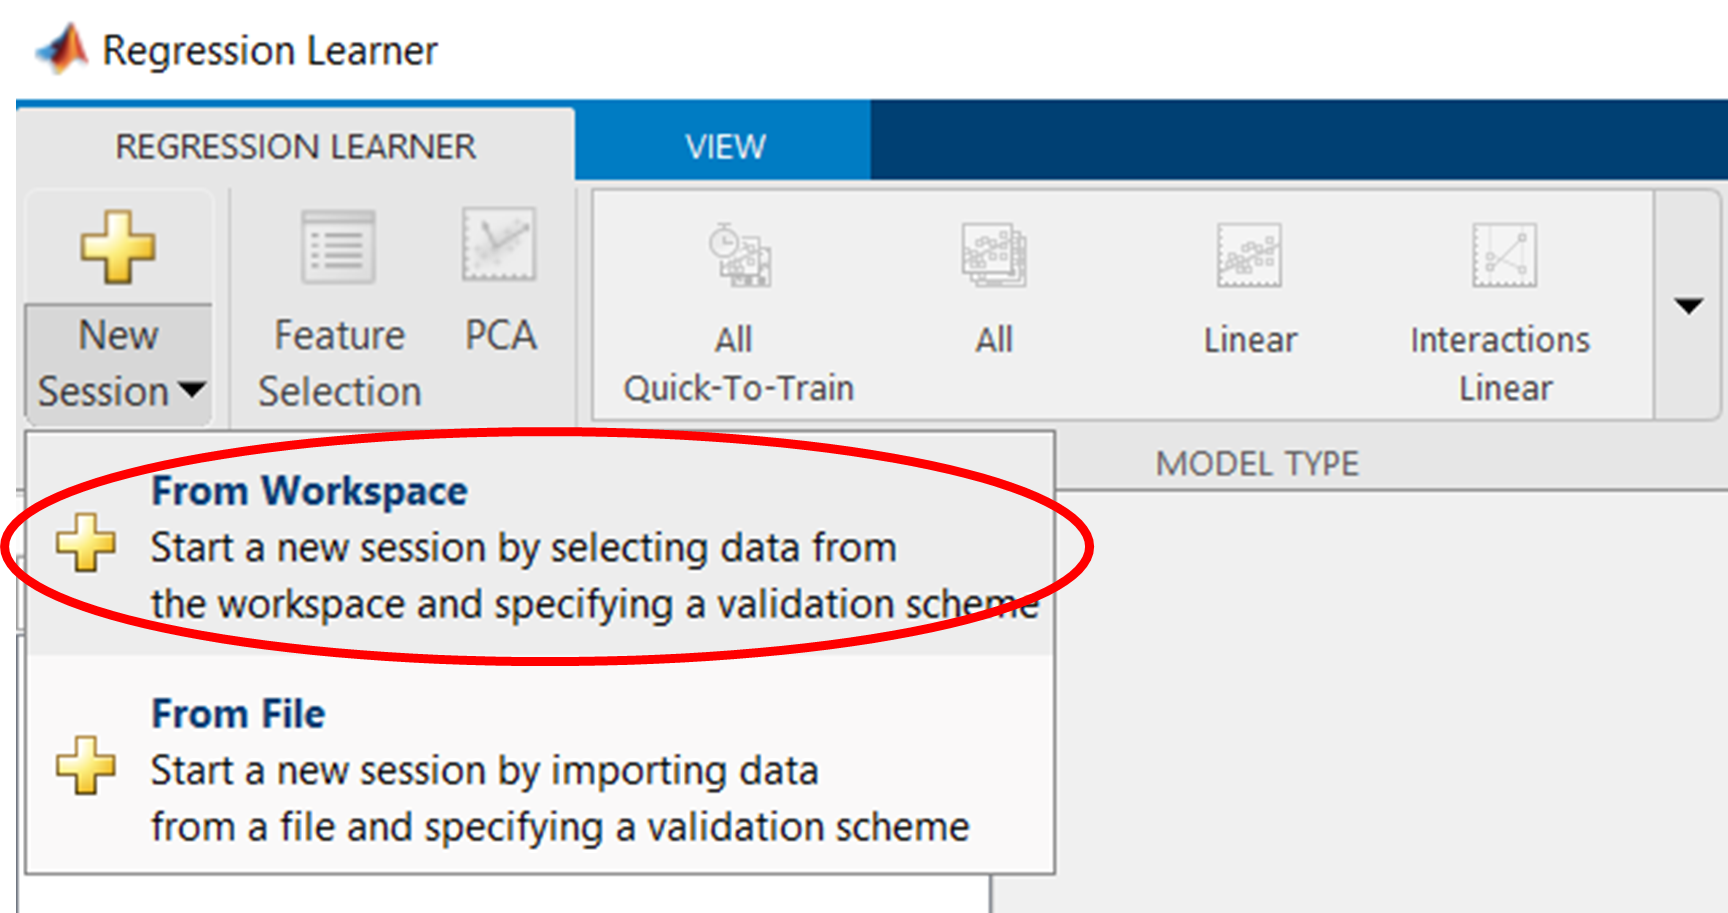

b) Choose the TrainNYC variable and be sure to select the `Load` variable as the **Response **from the drop-down list. Then click **Start Session**.

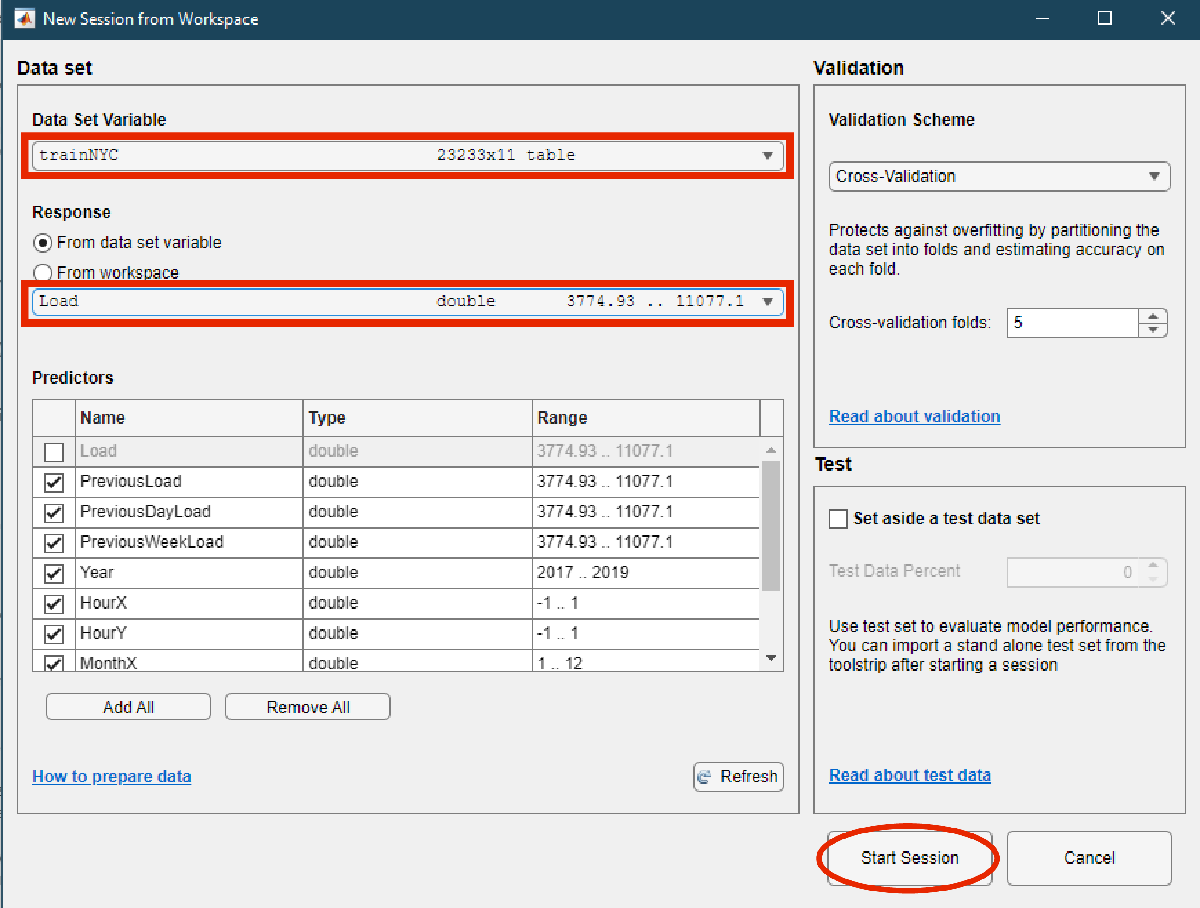

After importing the data you can train many different models. 

c) Use the drop-down in the **Models** section of the app toolstrip and select **All Quick-To-Train** models. Next, select **Train**.

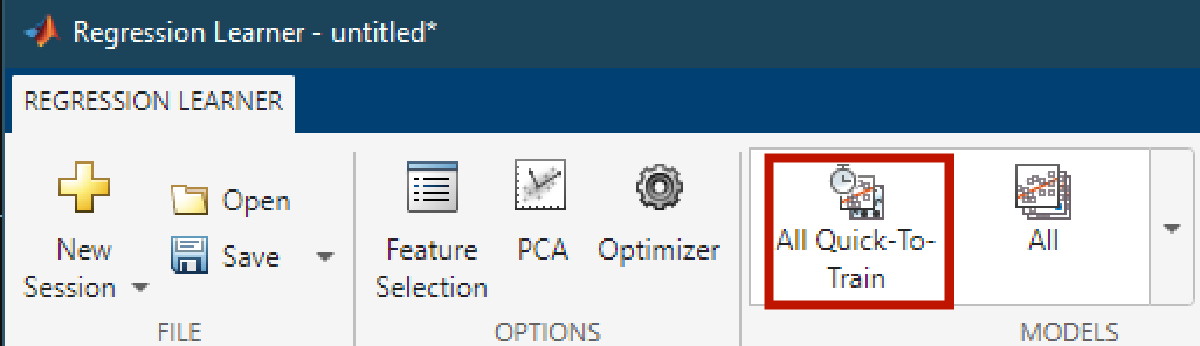

d) Use the same drop-down to select a new model type. This time, select the **Bagged Trees **model. Click **Train**.

e) Select a model in the **Models** pane (left) and see the different parameters in the **Current Model** pane.

f) Select a model in the **Models** pane (left) and then observe the different types of plots. To generate the plots, select a type from the **Plots** section of the app toolstrip.

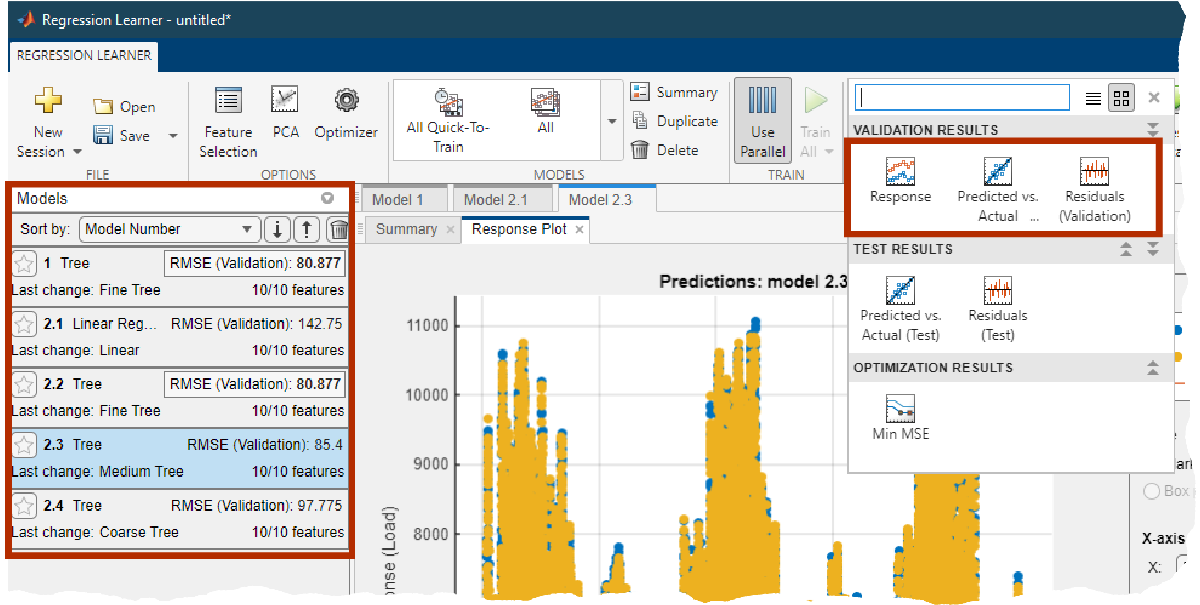

### **4.3. Save the trained model**

After deciding which of the models performs optimally, select the model in the **Model** pane on the left. Next, click the drop-down under **Export** and click **Export Model**. Name the model `TrainedModel`.

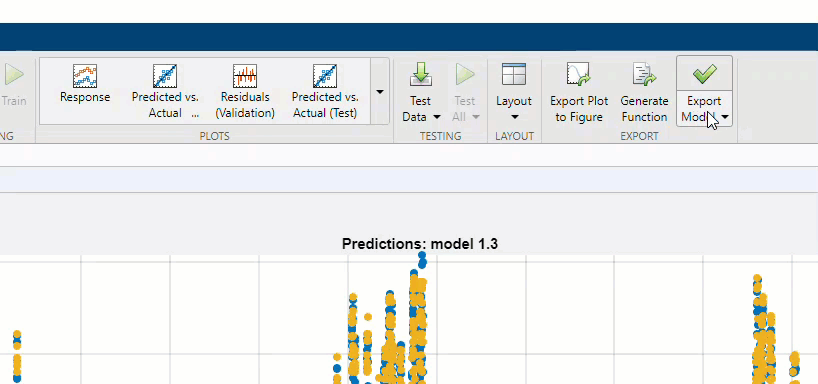

You can now minimize the Regression Learner app.

### 4.4. Apply and evaluate the model

#### **4.4.1. Predict future load**

You can now use the model to predict the future electricity load requirement. To test the model, use the TestNYC dataset.

***Task:**** Click the ****How to predict**** button to view the data in the variable *`XTest`* and learn how to use the exported model to make predictions.*

load model.mat
XTest = ans

XTest =   RegressionTree
             ResponseName: 'Y'
    CategoricalPredictors: []
        ResponseTransform: 'none'
          NumObservations: 24


  Properties, Methods


trainedModel.HowToPredict

ans =     'To make predictions on a new table, T, use: 
       yfit = c.predictFcn(T) 
     replacing 'c' with the name of the variable that is this struct, e.g. 'trainedModel'. 
      
     The table, T, must contain the variables returned by: 
       c.RequiredVariables 
     Variable formats (e.g. matrix/vector, datatype) must match the original training data. 
     Additional variables are ignored. 
      
     For more information, see How to predict using an exported model.'


***Task:**** Replace the code in the edit field below to use *`predictFcn`* with the exported model (TrainedModel) and get the predicted load for *`XTest`*. Click the *`Predict`* button to run the section.*

yTestPred = ans
 

#### **4.4.2. Evaluate the predictions**

Now that you have the measured load data for the test period, compare the predicted values to the actual ones by calculating the test RMSE. Plot the results. The app uses the RMSE metric for validating the models. Use the same measure to compute the error between the actual and the predicted loads for evaluating the model on the test data. 


$$\mathrm{RMSE}=\sqrt{\frac{\sum_{i=1}^N {\left(x_i -\hat{x_i } \right)}^2 }{N}}$$
 

where $x_i$ is the actual time series data and $\hat{x_i }$ is the predicted time series data.

***Task:**** Run this section using the ****Show plot data**** button. Observe the variables in the displayed timetable. What values does PlotTestData*`.Error`* contain?*

PlotTestData = table2timetable(NYCHourly(idxtest,:));
PlotTestData.Pred = yTestPred;
PlotTestData.Error = PlotTestData.Pred - PlotTestData.Load
 

***Task:**** Replace the code in the edit field below to compute the root mean-squared error (RMSE) using PlotTestData*`.Error`*. Analyze the predicted and actual (observed) load outputs. (****Hint:**** Use the *`mean`* and *`sqrt`* functions).*

rmse = ans;
 

PlotVars = {["Load" "Pred"], "Error"};
figure
stackedplot(PlotTestData,PlotVars, ...
    "Title", ["Comparison of actual and predicted load"; "Test RMSE= " + num2str(rmse)]);

## **5. Further Exploration**

- **Improve performance by further optimizing the model. ***Read the documentation page for the *[*Regression Learner app*](https://www.mathworks.com/help/stats/feature-selection-and-feature-transformation-using-regression-learner-app.html)*. Experiment with feature selection, PCA, and other optimization options. *

- [**Develop a model programmatically**](matlab:open('FE1_ProgrammaticML.mlx'))**.**

- [**Use deep learning to perform time series forecasting**](matlab:open('FE2_LoadForecastDL.mlx'))**.**